file = fullfile("doc","examples","fsae-ttc-data","fsaettc_obscured_testbench_drivebrake.mat");
parser = tydex.parsers.FSAETTC_SI_ISO_Mat_DriveBrake;
measurements = parser.run(file);
m = measurements(end);
disp(m)

  Measurement with properties:

    Metadata: [3×1 tydex.Metadata]
    Constant: [1×6 tydex.ConstantParameter]
    Measured: [1×12 tydex.MeasuredParameter]
    INCLANGL: 0.0559
    INFLPRES: 97000
    LONGSLIP: [612×1 single]
      FNOMIN: 2750
     NOMPRES: 97000
    SLIPANGL: 0
     LONGVEL: [612×1 single]
     RUNTIME: [612×1 single]
    WHROTSPD: [612×1 single]
          FX: [612×1 single]
         FYW: [612×1 single]
         FZW: 2750
         MXW: [612×1 single]
         MZW: [612×1 single]


measuredObjs = m.Measured;
measuredNames = {measuredObjs.Name};
I = strcmp(measuredNames, 'RUNTIME');
measuredObjs(I) = [];
measuredNames = {measuredObjs.Name};

sz = [numel(m.RUNTIME) numel(measuredObjs)];
type = class(m.RUNTIME);
tbl = timetable('Size', sz, ...
    'VariableTypes', repmat({type}, [1 sz(2)]), ...
    'RowTimes', seconds(m.RUNTIME), ...
    'VariableNames', measuredNames)

tbl = 612×11 timetable
       Time       LONGVEL    INFLPRES    WHROTSPD    LONGSLIP    FX    FYW    FZW    MXW    MZW    SLIPANGL    INCLANGL
    __________    _______    ________    ________    ________    __    ___    ___    ___    ___    ________    ________
    1259.6 sec       0          0           0           0        0      0      0      0      0        0           0    
    1259.6 sec       0          0           0           0        0      0      0      0      0        0           0    
    1259.6 sec       0          0     


for i = 1:numel(measuredObjs)
    measured = measuredObjs(i);
    data = measured.Data;
    name = measured.Name;
    tbl.(name) = data;
end

f = figure();
s = stackedplot(f, tbl)

s =   StackedLineChart with properties:

         SourceTable: [612×11 timetable]
    DisplayVariables: {'LONGVEL'  'INFLPRES'  'WHROTSPD'  'LONGSLIP'  'FX'  'FYW'  'FZW'  'MXW'  'MZW'  'SLIPANGL'  'INCLANGL'}
               Color: [0 0.4470 0.7410]
           LineStyle: '-'
           LineWidth: 0.5000
              Marker: 'none'
          MarkerSize: 6

  Show all properties

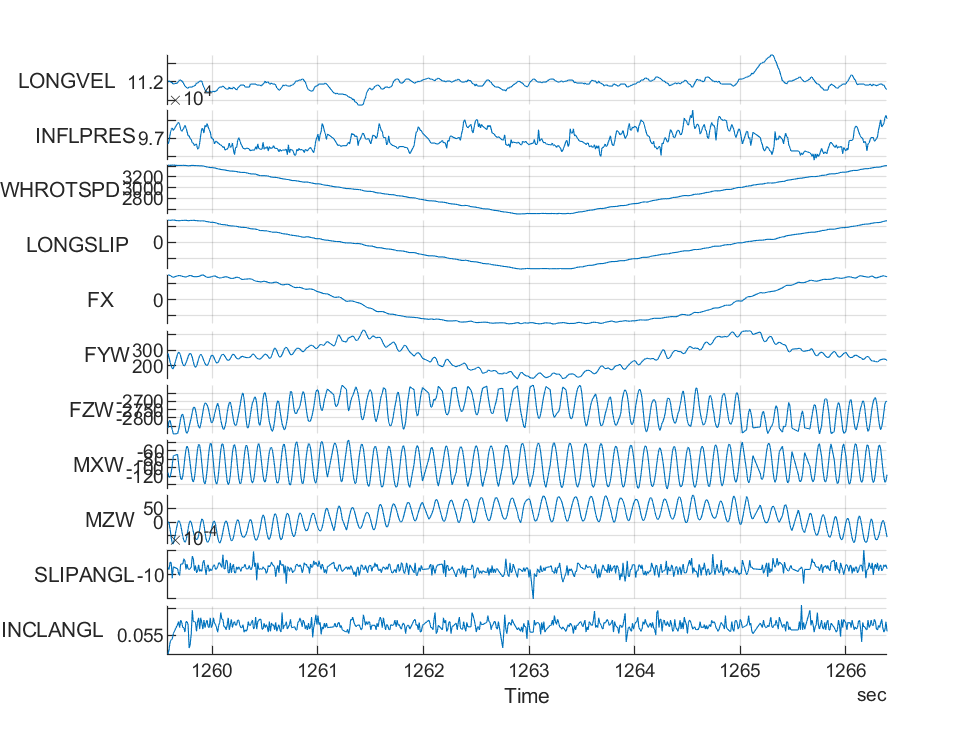

grid on